clc;clear;close all;

# EJERCICIO 8

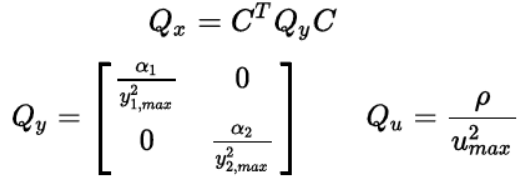

run('active_suspension_ctrl_design.m');

#### a) Verifique si el sistema es controlable.

W = [B A*B A^2*B A^3*B A^4*B];
if rank(W) == 5
    disp('Alcanzable y por lo tanto completamente controlable');
else
    disp('No es completamente controlable y el rango es:');
    disp(rank(W));
end

No es completamente controlable y el rango es:


     3



polos = eig(A)

polos = 	1.0e+03 *

  -0.0233 + 0.0702i
  -0.0233 - 0.0702i
  -0.0024 + 0.0070i
  -0.0024 - 0.0070i
  -1.0000 + 0.0000i


if all(real(polos)<0)
    disp('Estable')
end

Estable


#### b) Encuentre el valor de la matriz K para α 1 =α 2=1 y ρ=1 

y1max  = 0.05; % m
y2max  = 5;    % m/s^2
umax   = 1000; % N
alpha1 = 1;
alpha2 = 1;
rho    = 1;
Qy     = [alpha1/y1max^2 0; 0 alpha2/y2max^2];
Qu     = rho/umax^2;
Qx     = C.'*Qy*C;
K      = lqr(A, B, Qx, Qu, 0)

K = 	1.0e+03 *

   -3.5593    0.2450    4.8200    1.2208    0.0001


#### c) Encuentre el valor de kr.

kr   = -1/(C*((A-B*K)\B))

kr = 	1.0e+04 *

    3.0480         0


% Esto es en realidad una pseudo inversa o algo así, porque como se ve a
% continuación, la matriz que se invierte no se puede invertir porque es
% rectangular.

(C*(-(A-B*K)\B))

ans = 	1.0e+-4 *

    0.3281
    0.0000



(C*(-(A-B*K)\B))*kr

ans =     1.0000         0
    0.0000         0


#### d) Utilice el modelo en Simulink provisto para analizar la respuesta del sistema a una perturbación de 5 cm al pasar por arriba de un reductor de velocidad.

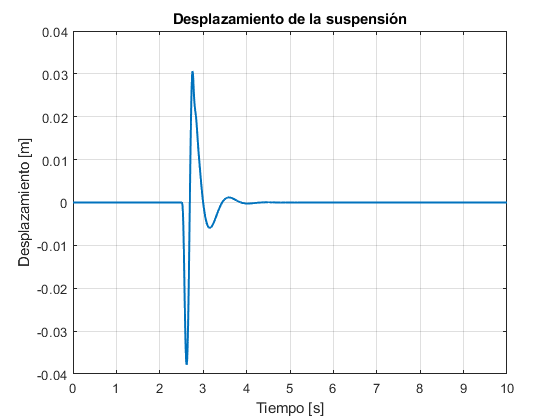


load("roaddist.mat")
sim('active_suspension_sim.slx');

tDisplacement   = Displacement.time;
DisplacementVal = Displacement.signals.values;

tAcceleration   = Acceleration.time;
AccelerationVal = Acceleration.signals.values;

tControl         = ControlSignal.time;
ControlSignalVal = ControlSignal.signals.values;

tRoad           = RoadDisturbanceMonitor.time;
RoadDisturbance = RoadDisturbanceMonitor.signals.values;

figure;
plot(tDisplacement, DisplacementVal, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Desplazamiento [m]');
title('Desplazamiento de la suspensión');
grid on;

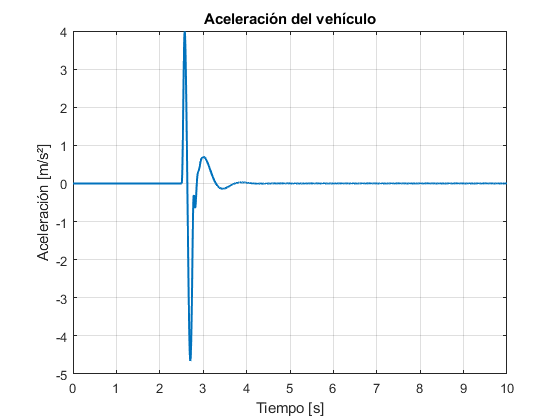


figure;
plot(tAcceleration, AccelerationVal, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Aceleración [m/s²]');
title('Aceleración del vehículo');
grid on;

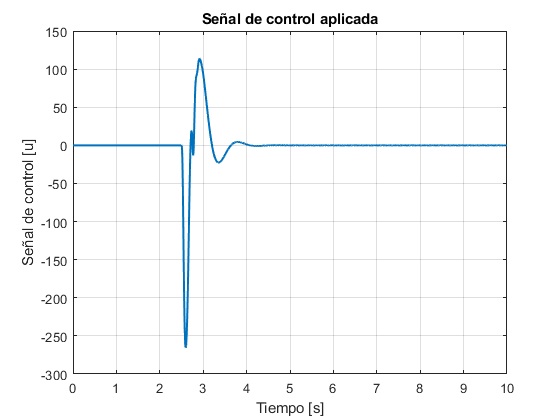


figure;
plot(tControl, ControlSignalVal, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Señal de control [u]');
title('Señal de control aplicada');
grid on;

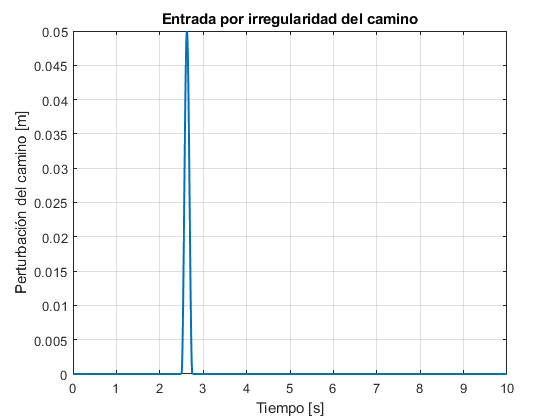


figure;
plot(tRoad, RoadDisturbance, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Perturbación del camino [m]');
title('Entrada por irregularidad del camino');
grid on;

# EJERCICIO 9

#### PREGUNTAS

- ¿Cuál es el desplazamiento máximo (valor absoluto) de la suspensión? **3.785 cm**

- ¿Cuál es la aceleración máxima (valor absoluto) del chasis? **4.658**

- ¿Cuál es el tiempo de asentamiento? Para este ejercicio, definimos el tiempo de estabilización como el tiempo que tarda el sistema en permanecer dentro del 5% de su valor de estado estable (es decir, 0,0025 m).** 0.95 s**

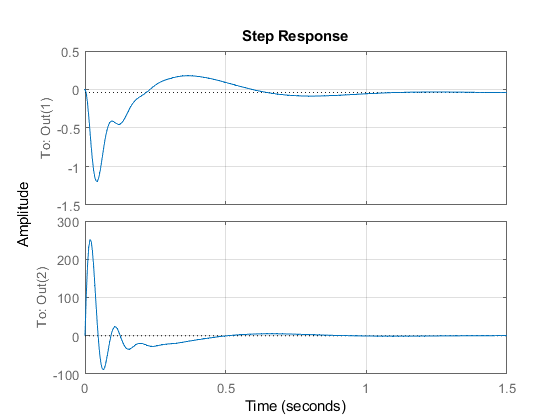

sys = ss(A-B*K, B1(:,2), C, [0;0]);
step(sys); grid on;

stepinfo(sys)

ans = 2×1 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


#### V O F

- Aumentar ρ da un tiempo de asentamiento más corto.

- Disminuir α1 y α2 proporciona un tiempo de asentamiento más largo.

- Disminuir α2 (α2 = 0) da una aceleración máxima mayor.

- El aumento de α1 proporciona una mayor aceleración máxima.

- El aumento de α1 proporciona un tiempo de asentamiento más largo.